# July 4th Updates 

## I. Gail 

For this week I read through the [Gail Documentation](http://mypages.iit.edu/~schoi32/GAIL_2_3_1/Documentation/gail_ug_2_3_1.pdf) and downloaded the necessary software. Gail seems to be very well made, and it could really help with the numerical integration of our project. However, there is one issue. All Gail methods require a functional input, and since our integration does not have a functional method, we cannot really use Gail's functionality. The only way we could Gail's numerical integration is to convert our vortex curves into a function (didn't you do something like this last week Scott? If so we might have  fixed the integration problem of our project!)

Another approach is to manually make Monte Carlo Integration. Even though it is costly, Monte Carlo integration can be quite accurate, and ithas little coding overhead. Thus it might be viable option to replace the use of $trapz$ in the BSI integration. 

## II. kB Fix and Expansion 

I also fixed the kB method, and had it working for all the respective ucrves we have looked at.

### Circle

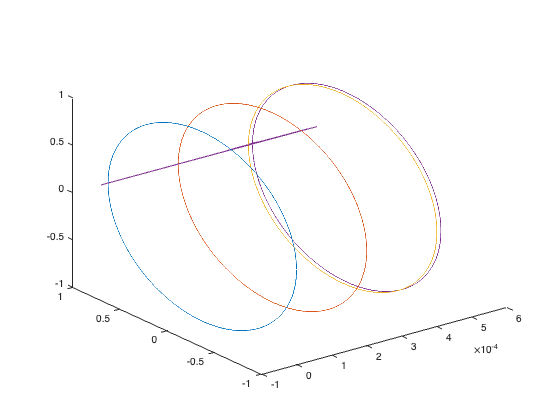

Curve_Evol('circle','kB',5000,3)

### Ellipse

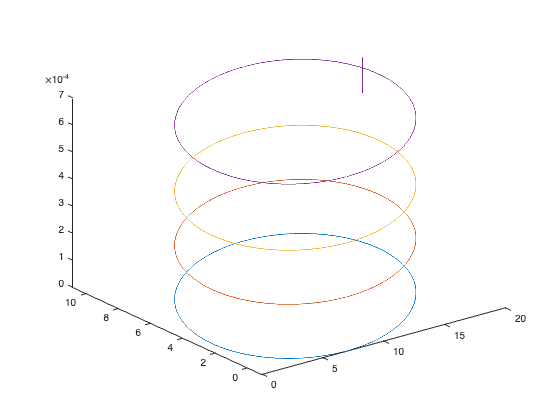

Curve_Evol('ellipse','kB',5000,3)

### Soliton

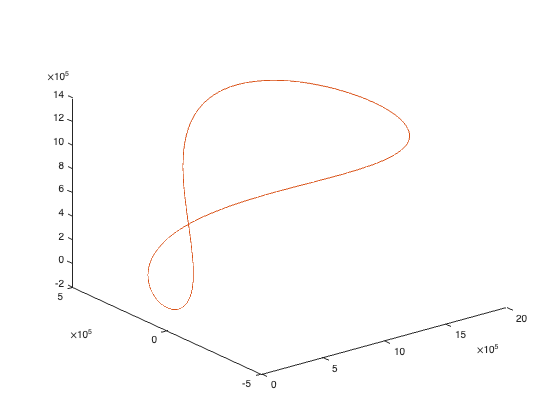

Curve_Evol('soliton','kB',5000,1)

Even though I updated the kB method, we still see a variety of errors. First, we see a Matlab error at the 3rd evolution of both the circle and ellipse. I looked into this, and it is a weird issue with the tangent of the previous evolution not computing correctly. I feel as though the $Derivative$ function I made is quite rigorous, so hopefully it is not the issue. I think the issue could eb the naive evolution of the curve we are doing (this is something I will mention later). 

Also, I implemented the kB expansion code, which has some very interesting properties when compared to kB.

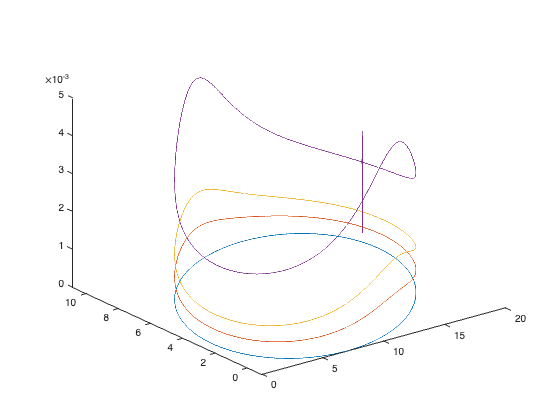

Curve_Evol('ellipse','kB+',5000,3)

We observe more dynamic behavior by the kB expansion, even though the evolution is halted by a Matlab error. 

## III. Organization 

This week I also did some heavy reorganization of the code. 

- I  put all the functions in a folder, and made a startup file that automatically puts them into the Matlab path. 

- I put all the applications of the functions into one folder, sorting them by the type of curve, and made 3 fiels for each type of function evolution (BSI,kB,kB Expansion). 

- I also cleaned up the code itself through refactoring so that it is easier to read and work with for both our sakes. 

## IV. Final Function

This is my favorite! This may be jumping a little ahead, but for the ease of use I made the Curve_Evol.m function. This function is an automatition of the whole process we have been working on. I have used it in this file for plotting (see above). This function takes in a curve type, function type, point count, and evolution number to generate graphs of the curves. This makes it very easy to see and compare the different outputs of curves and functions. Hopefully this helps on your end! 

## V. Moving Forward

The next steps in my opinion are fixing the naive evolution of the curve and numerical integration. For the evolution side, I think doing a single step of Euler's and then using one of the methods from Computational Methods for ODE's would be helpful. However, I would like some guidance on this part. Next for the numerical integration, there are two paths right now. One is making a functional way to take in our vortex curves, and the other is Monte Carlo Integration. I would also like some guidance in doing this part as well. 